- **ДАНО**

Вбить надо данные из дано, по таблицам сверять данные.

% Радиусы до источников
R1 = 2;
R2 = 8;
R3 = 8;
% Объем помещения
a = 10;
b = 20;
c = 5;
V = a * b * c

V = 1000

% Таблица с параметрами 
f =   [63  125 250 500 1000 2000 4000 8000];
Lw1 = [68  70  73  79  81   82   80   73]; % Для первого источника
Lw2 = [101 102 100 101 99   99   97   95]; % Для второго источника
Lw3 = [90  91  98  99  97   93   91   86]; % Для третьего источника
% Qшки
Q1 = 2*pi; % источник на полу
Q2 = pi; % источник на полу, прижат к стене
Q3 = pi; % источник подвешен, прижат к стене

- **РЕШЕНИЕ**

Si — площадь поверхности излучения i-ого источника, м2


$$S_i =\Omega_i R_i^2 \;\left\lbrack м^2 \right\rbrack$$


S1 = Q1 * R1^2;
S2 = Q2 * R2^2;
S3 = Q3 * R3^2;

В – акустическая постоянная помещения в м2, определяемая по формуле 4 из СНиП II-12–77.


$$B=B_{1000} \mu \;\left\lbrack м^2 \right\rbrack$$


$\mu$ по таблице по таблице 4

disp(V)

        1000



mu = [0.65 0.62 0.64 0.75 1 1.5 2.4 4.2]; % смотреть по таблице
B1000 = V / 20 % Тк у нас цех

B1000 = 50

% Найдем B
B = B1000 * mu

B =    32.5000   31.0000   32.0000   37.5000   50.0000   75.0000  120.0000  210.0000



$$L_j =L_{W_i } +10\;\lg \left(\frac{\Phi }{S_i }+\frac{4}{B}\right),\left\lbrack \textrm{дБ}\right\rbrack$$


F = 1;
Lj1 = Lw1 + 10 .* log10((F/S1 + 4./B))

Lj1 =    60.1183   62.2743   65.1693   70.6571   71.7842   71.6905   68.6405   60.6965


Lj2 = Lw2 + 10 .* log10((F/S2 + 4./B))

Lj2 =    92.0738   93.2712   91.1386   91.4782   88.2928   86.6572   82.8328   78.8059


Lj3 = Lw3 + 10 .* log10((F/S3 + 4./B))

Lj3 =    81.0738   82.2712   89.1386   89.4782   86.2928   80.6572   76.8328   69.8059


% ЧАСТЬ 2
LEj = 10 .* log10(10.^(0.1 .* Lj1) + 10.^(0.1 .* Lj2) + 10.^(0.1 .* Lj3))

LEj =    92.4083   93.6064   93.2697   93.6246   90.4764   87.7397   83.9362   79.3801


Ljdop = [95 87 83 78 75 73 71 69]

Ljdop =     95    87    83    78    75    73    71    69


for i = Ljdop - LEj
    if (i < 0)
        abs(i)
    else
        disp(0)
    end
end

     0



ans = 6.6064

ans = 10.2697

ans = 15.6246

ans = 15.4764

ans = 14.7397

ans = 12.9362

ans = 10.3801

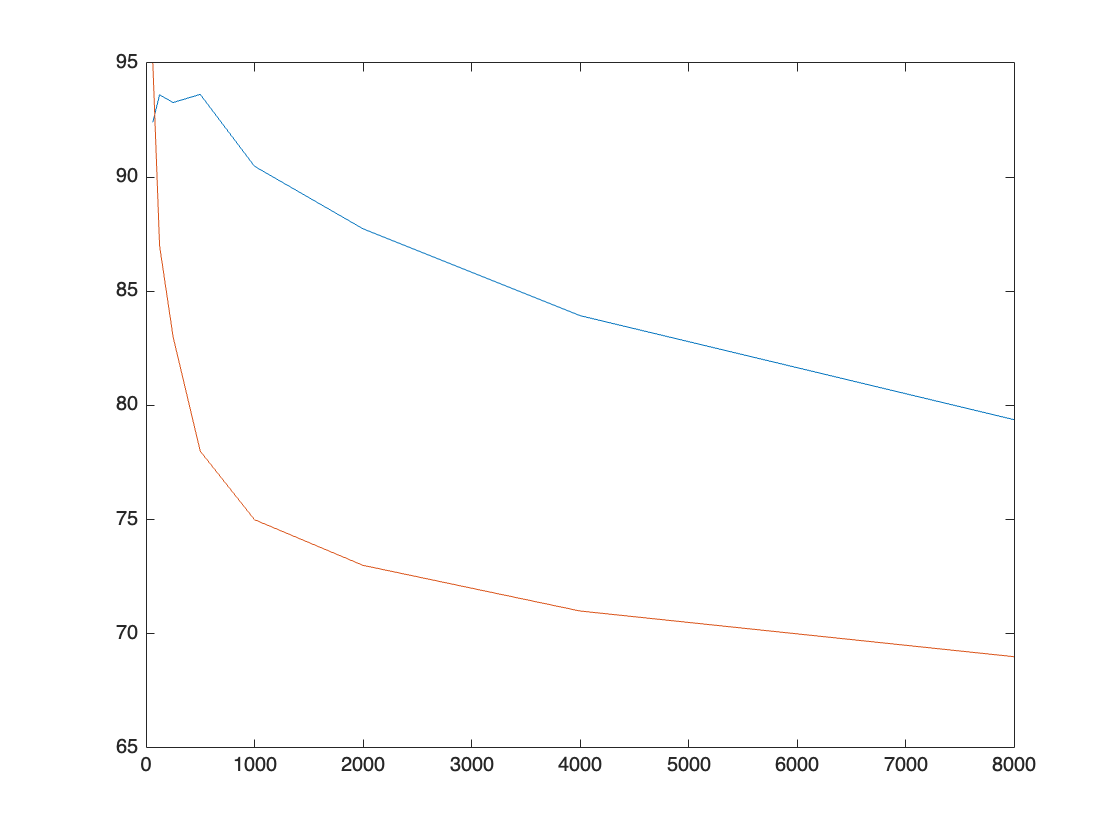


plot(f, LEj)
hold on;
plot(f, Ljdop)
saveas(gcf, 'pic.jpg')